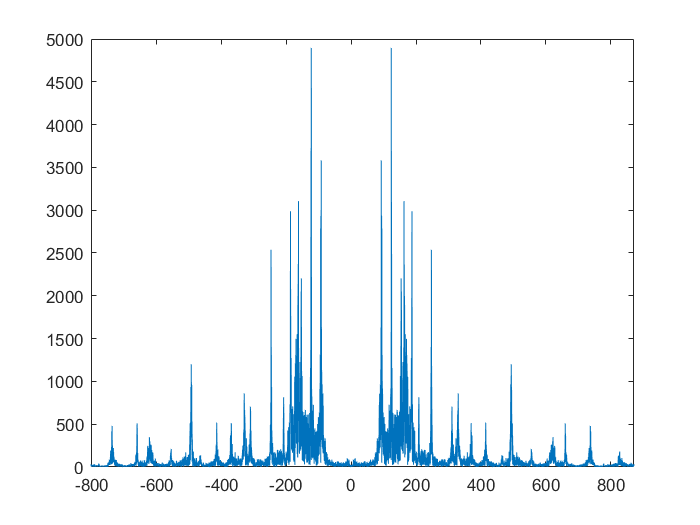

Fs = 44100;
samples = [1,5*Fs];
[y, Fs] = audioread("data/bensound-sunny.mp3", samples);
clf;
plot_FT(y(:,1), Fs);

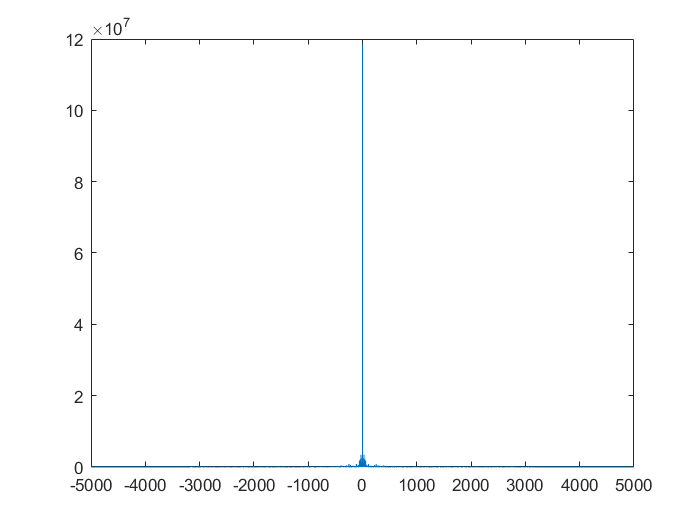

audiowrite("sunny10kFs.wav", y, 10000);
[y2, Fs2] = audioread("sunny10kFs.wav");
y2 = y2(:,1);
y2_rescaled = round(rescale(y2, 0, 1023));

plot_FT(y2_rescaled, Fs2);

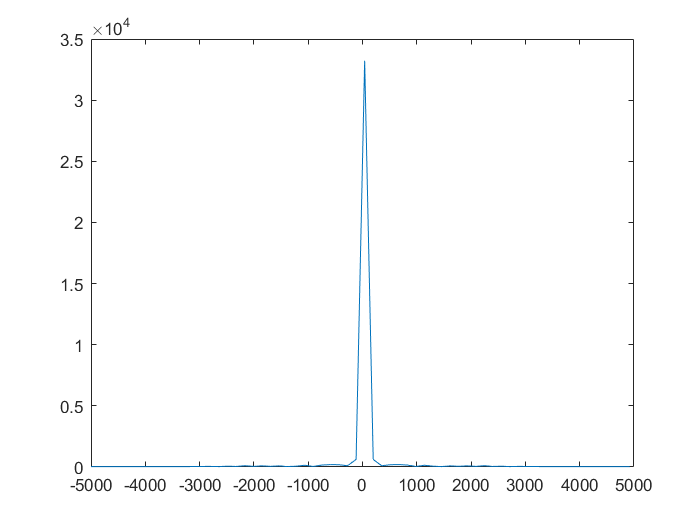

ans = 	1.0e+04 *

  -0.0029 + 0.0000i
  -0.0029 + 0.0001i
  -0.0027 - 0.0001i
  -0.0027 - 0.0003i
  -0.0029 - 0.0004i
  -0.0029 - 0.0007i
  -0.0029 - 0.0007i
  -0.0028 - 0.0010i
  -0.0025 - 0.0014i
  -0.0030 - 0.0017i


writematrix(y2_rescaled(4000:4127,:),"testmatrix.txt")
clf;
plot_FT(y2_rescaled(4000:4063,:), Fs2)